Jesús Molina Roldan

format long g;
clear;

# Exercici 1

beta = 0.5;
f = @(x) exp(x) - 0.5*(x^2) - 3;
a = 0;
b = 3;
maxiter = 1000;
tolf = 0.5*10^(-10);

a)

[alpha,rnbisection] = bisection(f,a,b,tolf,maxiter)


t =

     []



t = 36×5 table
    iter           a                   b                 alpha                 falpha        
    ____    ________________    ________________    ________________    _____________________

      0                    0                   3                 1.5        0.356689070338065
      1                    0                 1.5                0.75        -1.16424998338733
      2                 0.75                 1.5               1.125       -0.552595651081969
      3                1.125                 1.5              1.3125       -0.145877387058896
      4               1.3125                 1.5             1.40625       0.0918548037764602
      5               1.3125             1.40625            1.359375      -0.0301912535141651
      6             1.359375             1.40625           1.3

alpha =           1.37120730632159


rnbisection =         -0.417095566836396        -0.345128589118757        -0.746335695190342        -0.714016114561045        -0.907672604799139        -0.603358147460298           -2.317589559687         -0.30950117185744        -0.319627201762713        -0.336773638005008        -0.374530866931894         -0.46238788138009        -0.721502286607099        -0.920225138660586        -0.585585855271181         -1.71390139553664        -0.335968439123211         -0.37396238667801        -0.461669755268879        -0.719396847624825        -0.926726459828406        -0.579643724786113         -1.57699380294806        -0.349664059712072        -0.404439327987476        -0.540431136952174         -1.11785145104849        -0.459005136529973          -0.7098226470118        -0.959113681748492        -0.552444480577205         -1.21815392848713        -0.421389887311579        -0.588467050261907         -1.79863086865331


b)

[alpha,rnregulafalsi] = regulafalsi(f,a,b,tolf,maxiter)

t = 63×5 table
    iter            a            b           xn                    fxn         
    ____    _________________    _    _________________    ____________________

      0                     0    3     0.41136641260435       -1.57573303546444
      1      0.41136641260435    3    0.699405230611629       -1.23202849318659
      2     0.699405230611629    3    0.904535311183107      -0.938308553804019
      3     0.904535311183107    3     1.04992239395156      -0.693739161003253
      4      1.04992239395156    3     1.15179882108013      -0.499441215811986
      5      1.15179882108013    3     1.22234290866357      -0.351928184296919
      6      1.22234290866357    3     1.27069918458462      -0.243995082696332
      7      1.27069918458462    3     1.30358743766124      -0.167186423488907
      8      1

alpha =           1.37120730630495


rnregulafalsi =          0.253405484573845         0.203382249886299         0.151764109773713         0.108986175764326        0.0765936649827667        0.0531964210333701         0.036760827614078        0.0254156365918164        0.0176724014174821        0.0124267130783677       0.00889045890447214       0.00651436917214698       0.00492129662547705       0.00385475636897696       0.00314141388880607       0.00266461182146054       0.00234605214943787       0.00213327822309296       0.00199118853759688        0.0018963137133096       0.00183297018680393       0.00179068106847813       0.00176244927251973       0.00174360248529355       0.00173102109033506       0.00172262233644242       0.00171701575139482       0.00171327309423059       0.00171077474923145       0.00170910694300084       0.00170799366235103       0.00170725041099165       0.00170675431968229       0.00170642300586082       0.00170620244712124       0.00170605467601331       0.00170595547561093       0.0017058895098

c)

tolx = eps;
[alpha,rnsecant] = secant(f,a,b,tolx,tolf,maxiter)

xnmenos1 =      0


t = 8×4 table
    iter          xmas1                 fxmas1               xnmas1menosxn    
    ____    _________________    _____________________    ____________________

     0       0.41136641260435        -1.57573303546444       -2.58863358739565
     1      0.699405230611629        -1.23202849318659       0.288038818007279
     2       1.73189676702516         1.15162986212565        1.03249153641353
     3       1.23306349963351       -0.328496254766504      -0.498833267391648
     4       1.34377356563462      -0.0693815557157391       0.110710066001108
     5       1.37341772183528      0.00568552041959247      0.0296441562006646
     6       1.37117249710991    -8.94195097416173e-05    -0.00224522472537259
     7        1.3712072623017    -1.13079036800912e-07    3.47651917871339e-05


alpha =            1.3712072623017


rnsecant =          -1.30046938295712        -0.158980615443256        -0.788141903729535          -1.0418474717154        -0.737929163823244         -1.45341626774622         -2.11781829250478         -3.19798037963286


d)

df = @(x) exp(x) - x;
[alpha,rnnewton] = newton(f ,df, a ,maxiter,tolf,tolx)

t = 5×4 table
    iter           x                   falpha                alphamenosx     
    ____    ________________    ____________________    _____________________

     0                     2        2.38905609893065                        2
     1      1.55668375777259       0.531433818892716       -0.443316242227412
     2      1.38990093579116      0.0485400390931696       -0.166782821981429
     3      1.37140633175045    0.000511334152289322      -0.0184946040407075
     4      1.37120732898655     5.8227514365683e-08    -0.000199002763902056


alpha =           1.37120732898655


rnnewton =          -1.04229603440799         -0.52062630295391         -1.20509160398025         -2.26451757435194          -4.2444581611602


e)

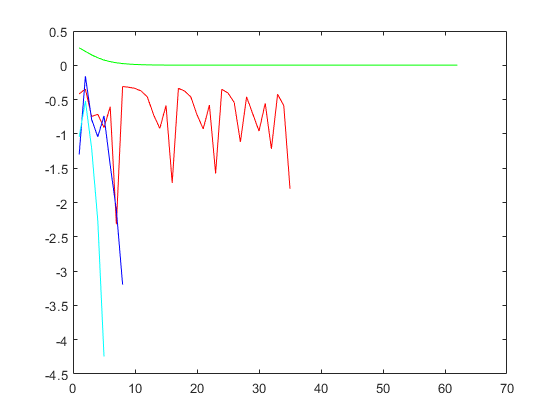

plot(1:length(rnbisection), rnbisection, 'r');
hold on
plot(1:length(rnregulafalsi), rnregulafalsi, 'g');
hold on
plot(1:length(rnsecant), rnsecant, 'b');
hold on
plot(1:length(rnnewton), rnnewton, 'c');
hold off

# exercici 2

a = 7;
N = 14;
[A, b] = ejercicio2(a, N);
n = Inf;

a)

%Metodo convergente
[xj, i] = metodoJacobi(A,b,n)

rhoJ =          0.540816290875753


xj =          0.323939433479458
         0.901364094298263
         0.985609214390124
         0.997900409923495
         0.999693654077089
         0.999955168900562
         0.999992528147324
         0.999992528147324
         0.999955168900562
         0.999693654077089


i =     28


b)

%Metodo convergente
[xj, i] = metodoGauss_Seidel(A,b,n)

rhoGS =           0.29245145551465


xj =          0.323939434198123
         0.901364092663589
         0.985609214636749
         0.997900409820987
         0.999693654106229
          0.99995516890257
         0.999992528168018
         0.999992528186087
         0.999955168964544
         0.999693654239411


i =     15


c)

[wo, rhoGS] = w_optima_Gauss_Seidel(A);

d)

[xj, i] = metodoGauss_Seidel_con_w(A,b,wo,n)

xj =          0.323939434636183
         0.901364092757492
         0.985609214655892
         0.997900409825845
         0.999693654109129
         0.999955168906126
         0.999992528172993
         0.999992528192676
         0.999955168972028
         0.999693654244692


i =     14


# exercici 3

a)

A = [10 20 30 40 50 60];
b = [1.4,2.8,3.6,5.0,6.4,7.2]';
A = [A',ones(size(A'))];
x = minimos_cuadrados(A,b)

x =          0.117714285714286
         0.279999999999999


r = norm(b-A*x,2)

r =           0.38840332498209


p = polyval(x,[10 20 30 40 50 60])

p =           1.45714285714286          2.63428571428571          3.81142857142857          4.98857142857143          6.16571428571429          7.34285714285714


plot([10 20 30 40 50 60],p);
xlim([10,60])

b)

A = [10 20 30 40 50 60];
A = [A'.^2,A',ones(size(A'))];
x = minimos_cuadrados(A,b)

x =      -0.000107142857142883
         0.125214285714288
         0.179999999999973


r = norm(b-A*x,2)

r =          0.382846481727896


p = polyval(x,[10 20 30 40 50 60])

p =           1.42142857142856          2.64142857142857          3.84000000000001          5.01714285714286          6.17285714285715          7.30714285714285


hold on
plot([10 20 30 40 50 60], p, 'r')

c)

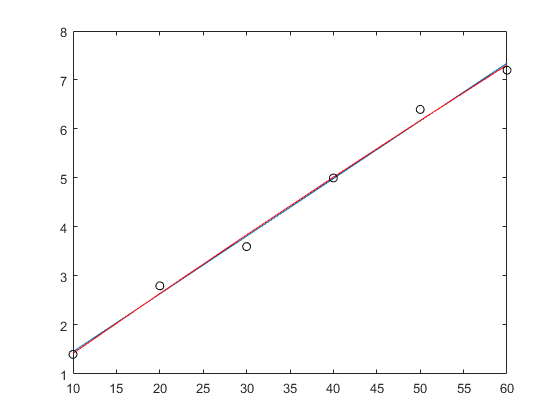

hold on
scatter([10 20 30 40 50 60], [1.4,2.8,3.6,5.0,6.4,7.2], 'k');
hold off;

%Com es pot veure per representar mejor una recta

# Exercici 4

p = @(x) x^3 - 6.1*x^2 + 3.2*x + 1.5;
x = 1.94;
y1 = p(x)

y1 =                  -7.948576


y1 = redondear(p(x),3)

y1 =                      -7.95


p = horner([1 -6.1 3.2 1.5], 1.94)

p =                  -7.948576


y2 = redondear(p,3)

y2 =                      -7.95


function [A, b] = ejercicio2(a, N)
    A = zeros(N);    
    for i = (1:N)
        A(i,i) = a;
        for j = (1:N)
            if abs(i-j) == 1
                A(i,j) = -1;
            end
        end
    end
    A(1,end) = a/2;
    A(end,1) = a/2;
    b = zeros(N,1)+(a-2);
    b(1) = (a/2)-1; b(end) = (a/2)-1;
end
function y=redondear(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = round(x*10^(t-e))*10^(e-t);
    return
end
function y = horner(c,x)
% HORNER   Evaluate a polynomial using Horner's rule. 
% Input:
%   c     Coefficients of polynomial, in descending order (vector)
%   x     Evaluation point (scalar)
% Output:
%   y     Value of the polynomial at x (scalar)
n = length(c);
y = c(1);
    for k = 2:n
        y = x.*y + c(k);
    end
end
function [alpha,rn]= secant(f,a,b,tolx,tolf,maxiter)
   rn = [];
   iter = 0;
   xnmenos1 = a
   xn = b;
   xnmas1 = xn-f(xn)*((xn-xnmenos1)/(f(xn)-f(xnmenos1)));
   t = [iter  xnmas1 f(xnmas1) (xnmas1-xn)];
   while (iter < maxiter && abs(xnmas1-xn) >= tolx && abs(f(xnmas1)) >= tolf )
        xnmenos1 = xn;
        xn = xnmas1;
        xnmas1 = xn-f(xn)*((xn-xnmenos1)/(f(xn)-f(xnmenos1)));
        iter = iter +1;
        t = [t; iter  xnmas1 f(xnmas1) (xnmas1-xn)];
        if (iter ~= 0)
            rn = [rn -log10(2*(abs(t(end) - t(end-1)))/abs(t(end)))];
        end
   end
   alpha = t(end-1, 2);
   t = array2table(t(1:end-1,:),'VariableNames',{'iter','xmas1', 'fxmas1', 'xnmas1menosxn'})
end
function [alpha,rn] = regulafalsi(f,a,b,beta,maxiter)
    rn = [];
    iter = 0;
    t = [];
    alpha= (f(b)*a-f(a)*b)/(f(b)-f(a));
    while(abs(b-a) > beta && iter < maxiter && abs(b-a) > eps && abs(f(alpha))>=beta)
        alpha= (f(b)*a-f(a)*b)/(f(b)-f(a));
        t = [t; iter a b alpha f(alpha)];
        if (iter ~= 0)
            rn = [rn -log10(2*(abs(t(end) - t(end-1)))/abs(t(end)))];
        end
        iter=iter+1;
        if(sign(f(alpha)) == sign(f(b)))
            b=alpha;
        else
            a=alpha;
        end
    end
    t = array2table(t,'VariableNames',{'iter','a', 'b', 'xn', 'fxn'})
end
function [alpha,rn] = bisection(f,a,b,eta,maxiter)
    rn = [];
    if (f(a)*f(b) >= 0)
        display('Error valores a y b');
    end
    iter = 0;
    alpha = (a+b)/2;
    t = []
    while(abs(b-a) > eta && iter < maxiter && abs(b-a) > eps && abs(f(alpha))>=eta)
        alpha = (a+b)/2;
        f_alpha = f(alpha);
        t = [t; iter a b alpha f_alpha];
        if (iter ~= 0)
            rn = [rn -log10(2*(abs(t(end) - t(end-1)))/abs(t(end)))];
        end
        iter = iter+1;
        if (sign(f(alpha)) == sign(f(b)))
            b = alpha;
        else
            a = alpha;
        end
    end
    t = array2table(t,'VariableNames',{'iter','a', 'b', 'alpha', 'falpha'})
end
function [alpha,rn]= newton(f ,df, a ,maxiter,tolf,tolx)
    rn = [];
    iter =  0;
    alpha = a - f(a)/df(a);
    t = [iter  alpha f(alpha) (alpha-a)];
    while (iter < maxiter && abs(alpha-a) >= tolx && abs(f(alpha)) >= tolf )
        a = alpha;
        alpha = a - f(a)/df(a);
        iter = iter +1;
        t = [t;iter  alpha f(alpha) (alpha-a)];
        if (iter ~= 0)
            rn = [rn -log10(2*(abs(t(end) - t(end-1)))/abs(t(end)))];
        end
    end
    alpha = t(end-1, 2);
    t = array2table(t(1:end-1,:),'VariableNames',{'iter','x', 'falpha', 'alphamenosx'})
end
function [x] = minimos_cuadrados(A,b)
    C = A'*A;
    d = A'*b;
    x = C\d;
end
function [xj, i] = metodoJacobi(A,b,n)
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    Bj=-d*(A-D);
    rhoJ=max(abs(eig(Bj)))
    cj=d*b;
    if (rhoJ >= 1) 
        display('mètode de JACOBI divergent');
    else
    % Iteracions del mètode Jacobi
        xj=zeros(size(b));
        i = 1;
        control = 2;
        while i<=n && control > 0.5*10^(-8)
             new=Bj*xj+cj;
             rj(i)=norm(A*new-b);
             control=norm(new-xj)/norm(new);
             xj=new;
             i = i +1;
        end
        i = i -1;
    end
end
function [xgs, i] = metodoGauss_Seidel(A,b,n)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(L+D);
    Bgs=-d*U;
    rhoGS=max(abs(eig(Bgs)))
    cgs=d*b;
    if (rhoGS >= 1 && false) 
        display('mètode de Gauss-Seidel divergent');
    else
    % Iteracions del mètode Gauss-Seidel
        B=Bgs; c=cgs;
        xgs=zeros(size(b));
        i = 1;
        control = 2;
        while i<=n && control > 0.5*10^(-8)
            new=B*xgs+c;
            rgs(i)=norm(A*new-b);
            control=norm(new-xgs)/norm(new);
            xgs=new;    
            i = i +1;
        end
        i = i-1;
    end
end
function [wo, rhoGS] = w_optima_Gauss_Seidel(A)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(L+D);
    Bgs=-d*U;
    rhoGS=max(abs(eig(Bgs)));
    wo = 2/(1+sqrt(1-(rhoGS^2)));
    %Obtener el radio espectral del coeficient espectral optim
    d = inv(wo*L+D);
    Bwgs=d*((1-wo)*D-wo*(U));
    rhoGS=max(abs(eig(Bwgs)));
end
function [xgsw,i] = metodoGauss_Seidel_con_w(A,b,w,n)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(D+w*L);
    Bw=d*((1-w)*D-w*U);
    cw=d*w*b;
    xgsw=zeros(size(b));
    i = 1;
    control = 2;
    while i<=n && control > 0.5*10^(-8)
        new=Bw*xgsw+cw;
        rgsw(i)=norm(A*new-b);
        control=norm(new-xgsw)/norm(new);
        xgsw=new;  
        i = i+1;
    end
    i = i -1;
end